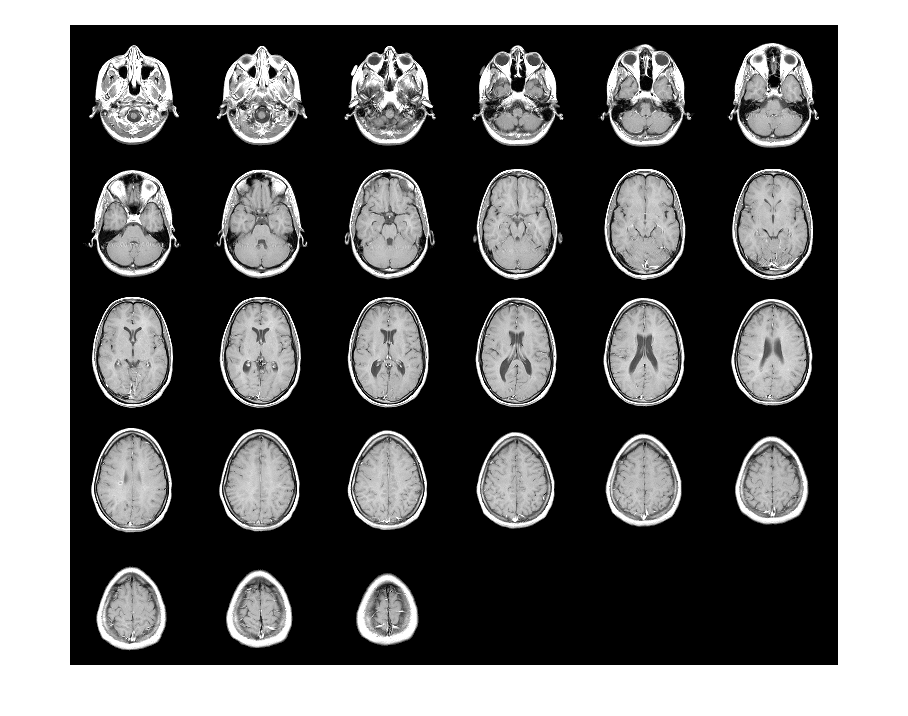

load mri;
montage(D,map)

## Step 2: Extract Sagittal Slice from Horizontal Slices Using IMTRANSFORM

We can construct a mid-sagittal slice from the MRI data by taking a subset of `D` and transforming it to account for the different sampling intervals and the spatial orientation of the dimensions of `D`.

The following statement extracts all the data needed for a midsagittal slice.

M1 = D(:,44,:,:); size(M1)

ans =    128     1     1    27


However we cannot view `M1` as an image because it is 128-by-1-by-1-by-27. `reshape` (or `squeeze`) can convert `M1` into a 128-by-27 image that is viewable with `imshow`.

M2 = reshape(M1,[128 27]); size(M2)

ans =    128    27


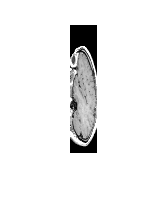

figure, imshow(M2,map);

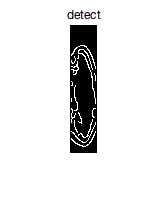

BW1 = edge(M2,'Canny');
figure, imshow(BW1);

title('detect');

The dimensions in `M2` are ordered as follows:

- Dimension 1: Front to back of head (rostral to caudal) 

- Dimension 2: Bottom to top of head (inferior to superior). 

We can obtain a much more satisfying view by transforming `M2` to change its orientation and increase the sampling along the vertical (inferior-superior) dimension by a factor of 2.5 -- making the sampling interval equal in all three spatial dimensions. We could do this in steps starting with a transpose, but the following affine transformation enables a single-step transformation and more economical use of memory.

T0 = maketform('affine',[0 -2.5; 1 0; 0 0]);

The upper 2-by-2 block of the matrix passed to maketform, `[0 -2.5;1 0]`, combines the rotation and scaling. After transformation we have:

- Dimension 1: Top to bottom of head (superior to inferior). 

- Dimension 2: Front to back of head (rostral to caudal) 

The call

imtransform(M2,T0,'cubic')

would suffice to apply `T` to `M2` and provide good resolution while interpolating along the top to bottom direction. However, there is no need for cubic interpolation in the front to back direction, since no resampling will occur along (output) dimension 2. Therefore we specify nearest-neighbor resampling in this dimension, with greater efficiency and identical results.

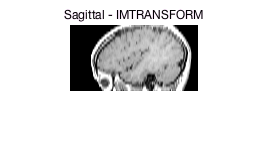

R2 = makeresampler({'cubic','nearest'},'fill');
M3 = imtransform(M2,T0,R2);  
figure, imshow(M3,map);
title('Sagittal - IMTRANSFORM')

T1 = maketform('affine',[-2.5 0; 0 1; 68.5 0]);  
inverseFcn = @(X,t) [X repmat(t.tdata,[size(X,1) 1])];
T2 = maketform('custom',3,2,[],inverseFcn,64);
Tc = maketform('composite',T1,T2);

R3 = makeresampler({'cubic','nearest','nearest'},'fill');

`tformarray` transforms the three spatial dimensions of `D` to a 2-D output in a single step. Our output image is 66-by-128, with the original 27 planes expanding to 66 in the vertical (inferior-superior) direction.

M4 = tformarray(D,Tc,R3,[4 1 2],[1 2],[66 128],[],0);

The result is identical to the previous output of `imtransform`.

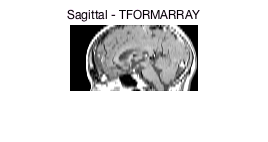

figure, imshow(M4,map);
title('Sagittal - TFORMARRAY');

## Step 4: Create and Display Sagittal Slices

We create a 4-D array (the third dimension is the color dimension) that can be used to generate an image sequence that goes from left to right, starts 30 planes in, skips every other plane, and has 35 frames in total. The transformed array has:

- Dimension 1: Top to bottom (superior to inferior) 

- Dimension 2: Front to back (rostral to caudal) 

- Dimension 4: Left to right. 

As in the previous step, we permute the input array using  `TDIMS_A = [4 1 2]`, again flipping and rescaling/resampling the vertical dimension. Our affine transformation is the same as the T1 above, except that we add a third dimension with a (3,3) element of 0.5 and (4,3) element of -14 chosen to map 30, 32, ... 98 to 1, 2, ..., 35. This centers our 35 frames on the mid-sagittal slice.

T3 = maketform('affine',[-2.5 0 0; 0 1 0; 0 0 0.5; 68.5 0 -14]);

In our call to `tformarray`, `TSIZE_B = [66 128 35]` now includes the 35 frames in the 4th, left-to-right dimension (which is the third transform dimension). The resampler remains the same.

S = tformarray(D,T3,R3,[4 1 2],[1 2 4],[66 128 35],[],0);

View the sagittal slices as a montage (padding the array slightly to separate the elements of the montage).

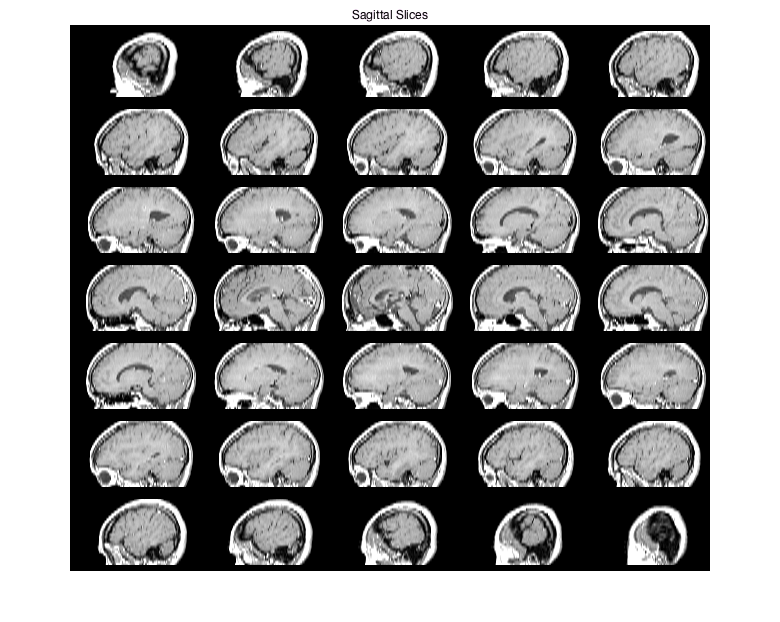

S2 = padarray(S,[6 0 0 0],0,'both');
figure, montage(S2,map)
title('Sagittal Slices');

## Step 5: Create and Display Coronal Slices

Constructing coronal slices is almost the same as constructing sagittal slices. We change `TDIMS_A` from `[4 1 2]` to `[4 2 1]`. We create a series of 45 frames, starting 8 planes in and moving from back to front, skipping every other frame. The dimensions of the output array are ordered as follows:

- Dimension 1: Top to bottom (superior to inferior) 

- Dimension 2: Left to right 

- Dimension 4: Back to front (caudal to rostral). 

T4 = maketform('affine',[-2.5 0 0; 0 1 0; 0 0 -0.5; 68.5 0 61]);

In our call to `tformarray`, `TSIZE_B` = [66 128 48] specifies the vertical, side-to-side, and front-to-back dimensions, respectively. The resampler remains the same.

C = tformarray(D,T4,R3,[4 2 1],[1 2 4],[66 128 45],[],0);

Note that all array permutations and flips in steps 3, 4, and 5 were handled as part of the `tformarray` operation.

View the coronal slices as a montage (padding the array slightly to separate the elements of the montage).

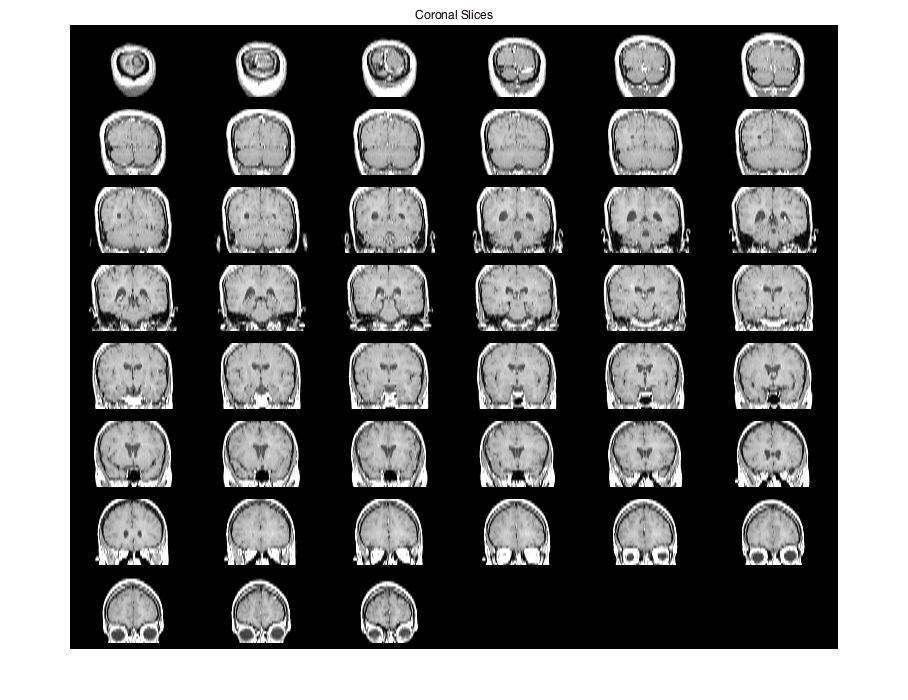

C2 = padarray(C,[6 0 0 0],0,'both');
figure, montage(C2,map)
title('Coronal Slices');